# mAD 0914 Merge

## merge round 1 dots and rotate

input_path = fullfile("D:/2020-10-09-mAD/AD_mouse9498/output/max/");
input_dim = [3072 3072 30 4];

% input_path = fullfile("F:/2020-09-14-mAD/AD_mouse9723/output/max/");
% input_dim = [3072 3072 30 4];


data_dirs = dir(fullfile(input_path, "tile_*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);

Ndirs = numel(data_dirs);
upd = textprogressbar(Ndirs, 'updatestep', 1);

% Iterate through each tile folder
for p=1:Ndirs
    
    curr_data_dir = data_dirs{p};
    curr_path = fullfile(input_path, curr_data_dir, "registered_image", "round1");
    curr_out_path = fullfile(input_path, "round1_merged_rotated");
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
    
    curr_files = dir(fullfile(curr_path, "*.tif"));
    curr_img = zeros(input_dim, 'uint8');
    
    for i=1:4
        curr_file_path = fullfile(curr_path, curr_files(i).name);
        curr_img(:,:,:,i) = new_LoadMultipageTiff(curr_file_path, 'uint8', 'uint8', false);
    end
    
    % merge four channels 
    curr_max = max(curr_img, [], 4);
    curr_max = imrotate(curr_max, -90); % rotate the image clockwise by 90 degrees
    
    curr_fname = fullfile(curr_out_path, sprintf("%s.tif", curr_data_dir));
    if exist(curr_fname, 'file') == 2
        delete(curr_fname);
    end
    
    for j=1:input_dim(3)
        imwrite(curr_max(:,:,j), curr_fname, 'writemode', 'append');        
    end
    
    upd(p);
end

## rotate merged dots, pi, tau, plaque

categories = ["merged_dots", "pi", "plaque", "tau"];

for curr_category=categories
    curr_path = fullfile(input_path, curr_category);
    curr_files = dir(fullfile(curr_path, "*.tif"))
    % input_files = struct2table(input_files);
    % input_files = natsort(input_files.name);
    
    Nfiles = numel(curr_files);
    upd = textprogressbar(Ndirs, 'updatestep', 1);
    
    curr_out_path = fullfile(input_path, sprintf("%s_rotated", curr_category));
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
    
    for p=1:Nfiles
        curr_file = fullfile(curr_path, curr_files(p).name);
        curr_img = new_LoadMultipageTiff(curr_file, 'uint8', 'uint8', false);
        curr_img = imrotate(curr_img, -90);
        
        curr_fname = fullfile(curr_out_path, curr_files(p).name);
        if exist(curr_fname, 'file') == 2
            delete(curr_fname);
        end
        
        for j=1:input_dim(3) 
            imwrite(curr_img(:,:,j), curr_fname, 'writemode', 'append');        
        end
        
        upd(p);
    end

end

## Stitch images with Fiji

## plot dapi centroid

base_path = "D:/2020-10-09-mAD/AD_mouse9498/output/max/stitched_ztrimmed_images_2d/"
dapi_seg_file = fullfile(base_path, "pi_sum_seg_74.tif");
dapi = imread(dapi_seg_file);

nissl_file = fullfile(base_path, "dots_pi_max_overlay.tif");
nissl = imread(nissl_file);

centroid = regionprops(dapi, "Centroid");
centroid = struct2table(centroid);
centroid = int16(centroid.Centroid);

plot_centroids(centroid, nissl, 4)

## Merge dots

% merge dots 
stitch_file = fullfile("D:/2020-10-09-mAD/AD_mouse9498/output/max/pi_rotated/TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y' 'z'};
TileConfiguration.x = int16(TileConfiguration.x);
TileConfiguration.y = int16(TileConfiguration.y);
head(TileConfiguration, 5)

%% Clear temporary variables
clear opts


base_path = fullfile("D:/2020-10-09-mAD/AD_mouse9498/output/max/");
trim_range = (2:26);
nrows = 8;
ncols = 7;

merged_row_points = {};
merged_row_reads = {};

counts = [];

a = 1;
for r=1:nrows
    row_points = int32([]);
    row_reads = {};
    for c=1:ncols
        curr_row = table2cell(TileConfiguration(a, :));
        a = a + 1;
        [tile, x, y, z] = curr_row{:};
        
        curr_dot_file = fullfile(base_path, sprintf("tile_%d", tile), "goodPoints_max3d.mat");
        load(curr_dot_file);
        counts = [counts; numel(tile_goodReads)];
        
        % rotate
        temp = tile_goodSpots;
        tile_goodSpots(:, 2) = temp(:, 1);
        tile_goodSpots(:, 1) = 3073 - temp(:, 2);
        
        % trim along z
        toKeep = ismember(tile_goodSpots(:,3), trim_range);
        tile_goodSpots = tile_goodSpots(toKeep, :);
        tile_goodReads = tile_goodReads(toKeep);
        
        tile_goodSpots = int32(tile_goodSpots) + int32([x y z]);
        if isempty(row_points)
            row_points = tile_goodSpots;
            row_reads = tile_goodReads;
        else
            duplicate_dots = tile_goodSpots(:, 1) <= max(row_points(:, 1)) & tile_goodSpots(:, 2) <= max(row_points(:, 2));
            tile_goodSpots = tile_goodSpots(~duplicate_dots, :);
            tile_goodReads = tile_goodReads(~duplicate_dots);
            row_points = [row_points; tile_goodSpots];
            row_reads = [row_reads; tile_goodReads];
        end

    end
    
    merged_row_points{end+1} = row_points;
    merged_row_reads{end+1} = row_reads;
end

merged_points = int32([]);
merged_reads = {};

for r=1:nrows
    curr_row_points = merged_row_points{r};
    curr_row_reads = merged_row_reads{r};
    
    if isempty(merged_points)
        % merged_points = [merged_points; curr_row_points];
        % merged_reads = [merged_reads; curr_row_reads];
        merged_points = curr_row_points;
        merged_reads = curr_row_reads;
    else
        duplicate_dots = curr_row_points(:, 1) <= max(merged_points(:, 1)) & curr_row_points(:, 2) <= max(merged_points(:, 2));
        curr_row_points = curr_row_points(~duplicate_dots, :);
        curr_row_reads = curr_row_reads(~duplicate_dots);
        merged_points = [merged_points; curr_row_points];
        merged_reads = [merged_reads; curr_row_reads];
    end
    
    
end

histogram(counts)

base_path = fullfile("D:/2020-10-09-mAD/AD_mouse9498/");
[ geneToSeq, seqToGene ] = new_LoadCodebook( base_path, 5, true );

% plot dots on round 1 
% background_file = fullfile("D:/2020-10-09-mAD/AD_mouse9498\output\max\stitched_ztrimmed_images_2d\pi_sum.tif");
background_file = fullfile("D:\2020-10-09-mAD-reads-assignment\AD_mouse9498\trimmed_images\pi_sum.tif")

background_file = "D:\2020-10-09-mAD-reads-assignment\AD_mouse9498\trimmed_images\pi_sum.tif"

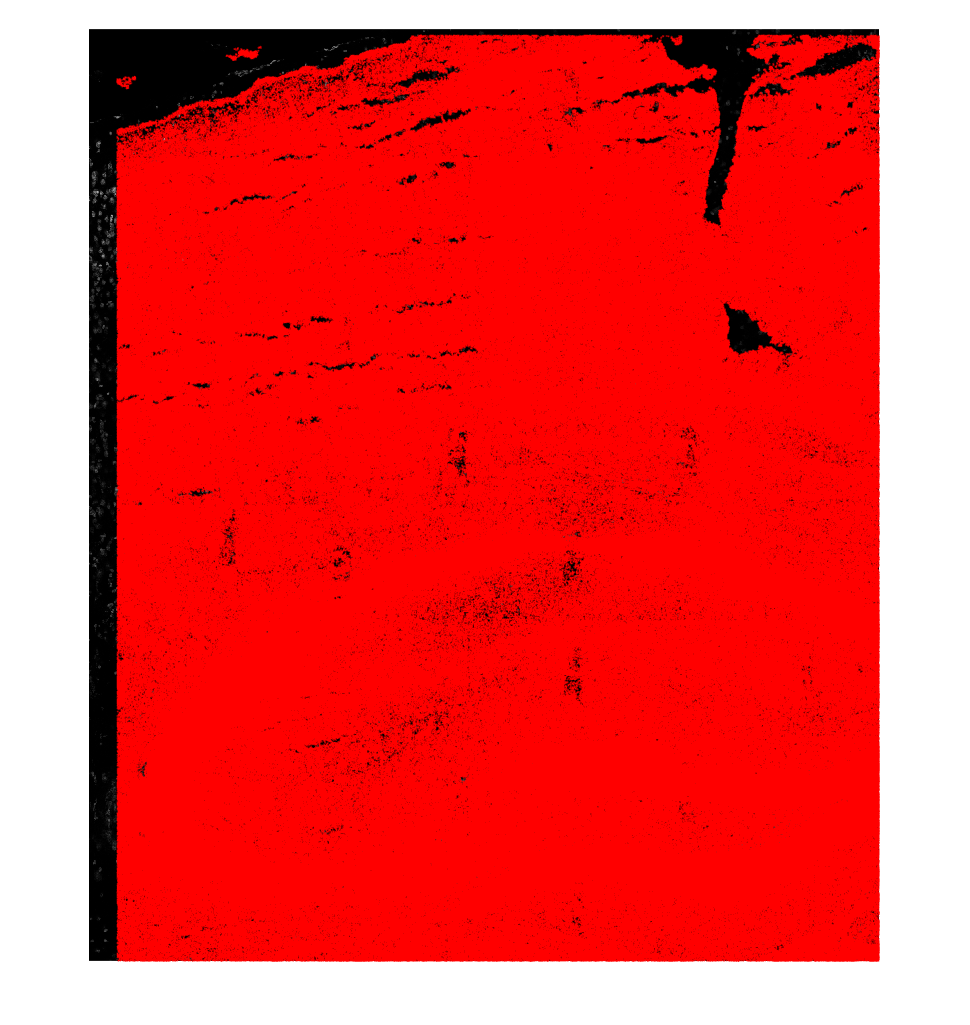

bk_img = imread(background_file);

plot_centroids(merged_points, bk_img, 0.1)

[C,ia,ic] = unique(merged_reads);
a_counts = accumarray(ic,1);
value_counts = table(C, a_counts);
value_counts = sortrows(value_counts, 'a_counts', 'descend');
genes = cellfun(@(x) seqToGene(x), value_counts.C, 'UniformOutput', false);
value_counts.genes = genes;
top5 = value_counts.genes(1:20);
curated = {"SLC17A7"; "CUX2"; "RORB"; "SULF2"; "PCP4"; "GAD1"; "PVALB"; "SST"; "MBP"; "MOBP"};
selected_genes = [top5; curated];

background_file = fullfile("D:/2020-10-09-mAD/AD_mouse9498\output\max\stitched_ztrimmed_images_2d\pi_sum.tif");
bk_img = imread(background_file);
saveAS = true;

curr_out_path = fullfile("D:/2020-10-09-mAD/AD_mouse9498\output\max\figures\");
for i=1:numel(selected_genes)
    gene = selected_genes{i};
    seq = geneToSeq(gene);
    good_points = ismember(merged_reads, seq);
    good_points = merged_points(good_points, :);
    
    nreads = value_counts(value_counts.genes == string(gene), :).a_counts;
    
    fh = figure; 
    ah = axes('Units','Normalize','Position', [0 0 1 1]);
    imshow(bk_img)
    hold on
    plot(good_points(:,1), good_points(:,2), '.', "Color", 'red', "MarkerSize", 2)
    hold off
    axis(ah, 'square');
    fh.Position(3) = fh.Position(4);
%     camroll(180)
    
    if saveAS
        fig_name = fullfile(curr_out_path, sprintf("%d_%s_%d.png", i, gene, nreads));
        saveas(gcf, fig_name)
    end
    
end

fh = figure; 
ah = axes('Units','Normalize','Position', [0 0 1 1]);
imshow(bk_img)
hold on
plot(good_points(:,1), good_points(:,2), '.', "Color", 'red', "MarkerSize", 2)
hold off
axis(ah, 'square');
fh.Position(3) = fh.Position(4);
camroll(180)

save("D:/2020-10-09-mAD/AD_mouse9498\output\max\merged_goodPoints_max3d.mat", "merged_points", "merged_reads");